# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'docx';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp


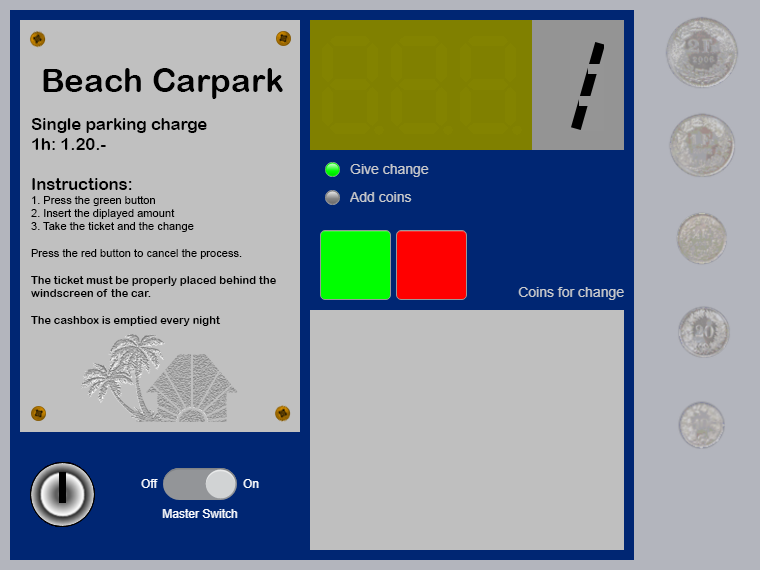

. Processing the test case #1...


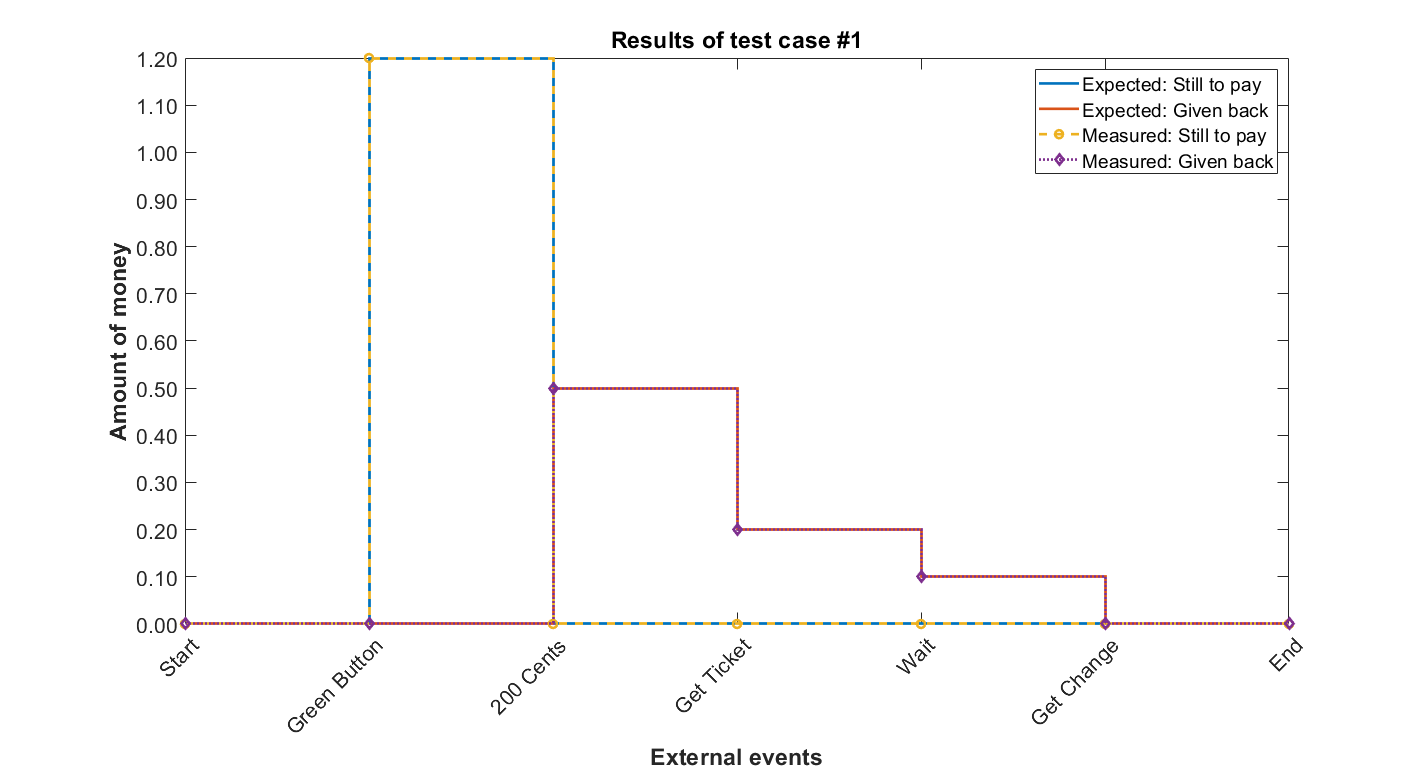


[Terse] Diagnostic logged (2021-02-17 10:55:04):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_7c91043d-d49d-401d-9168-095458dbb6ac.fig
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_7c91043d-d49d-401d-9168-095458dbb6ac.png
.

 Processing the test case #2...


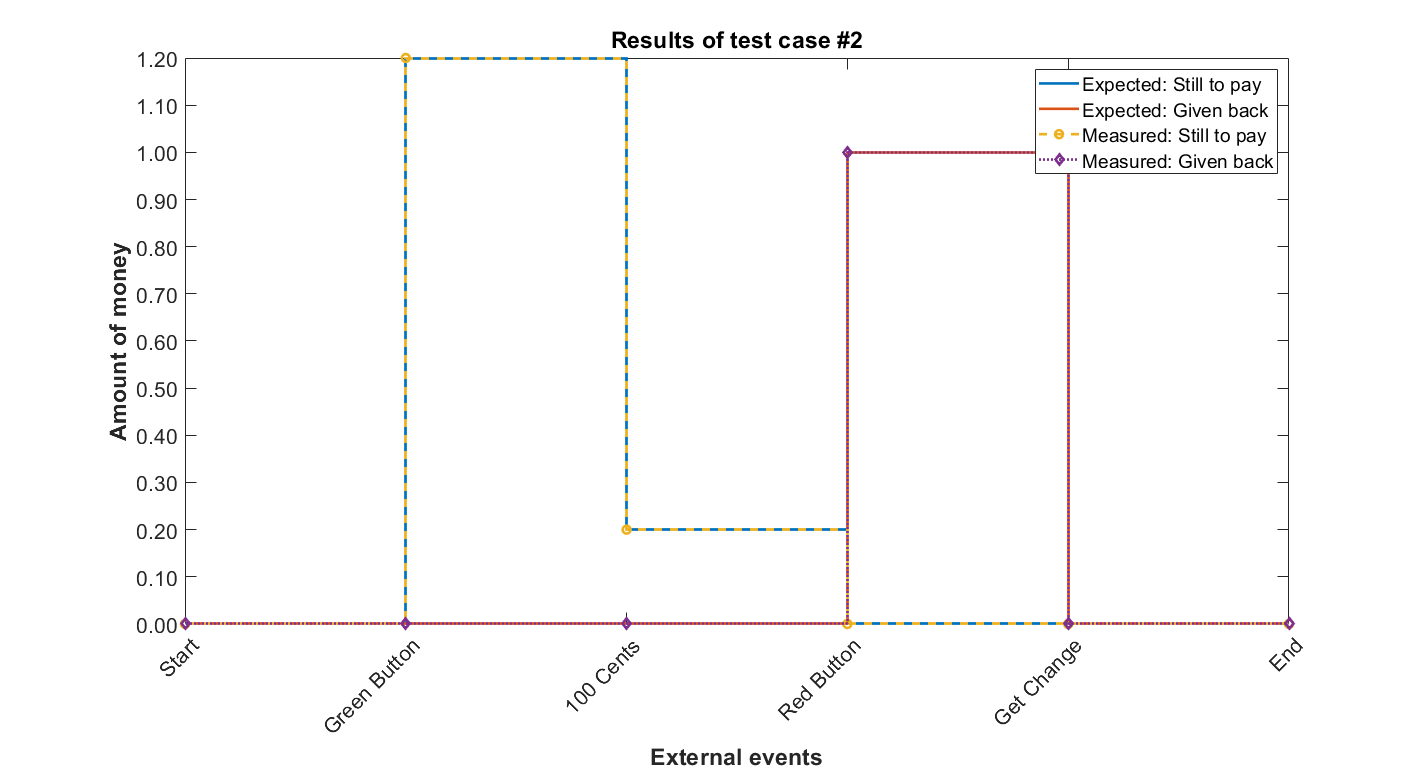


[Terse] Diagnostic logged (2021-02-17 10:55:29):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_d3c9a07a-ef68-44f8-ac9b-23a511196d2f.fig
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_d3c9a07a-ef68-44f8-ac9b-23a511196d2f.png
.

 Processing the test case #3...


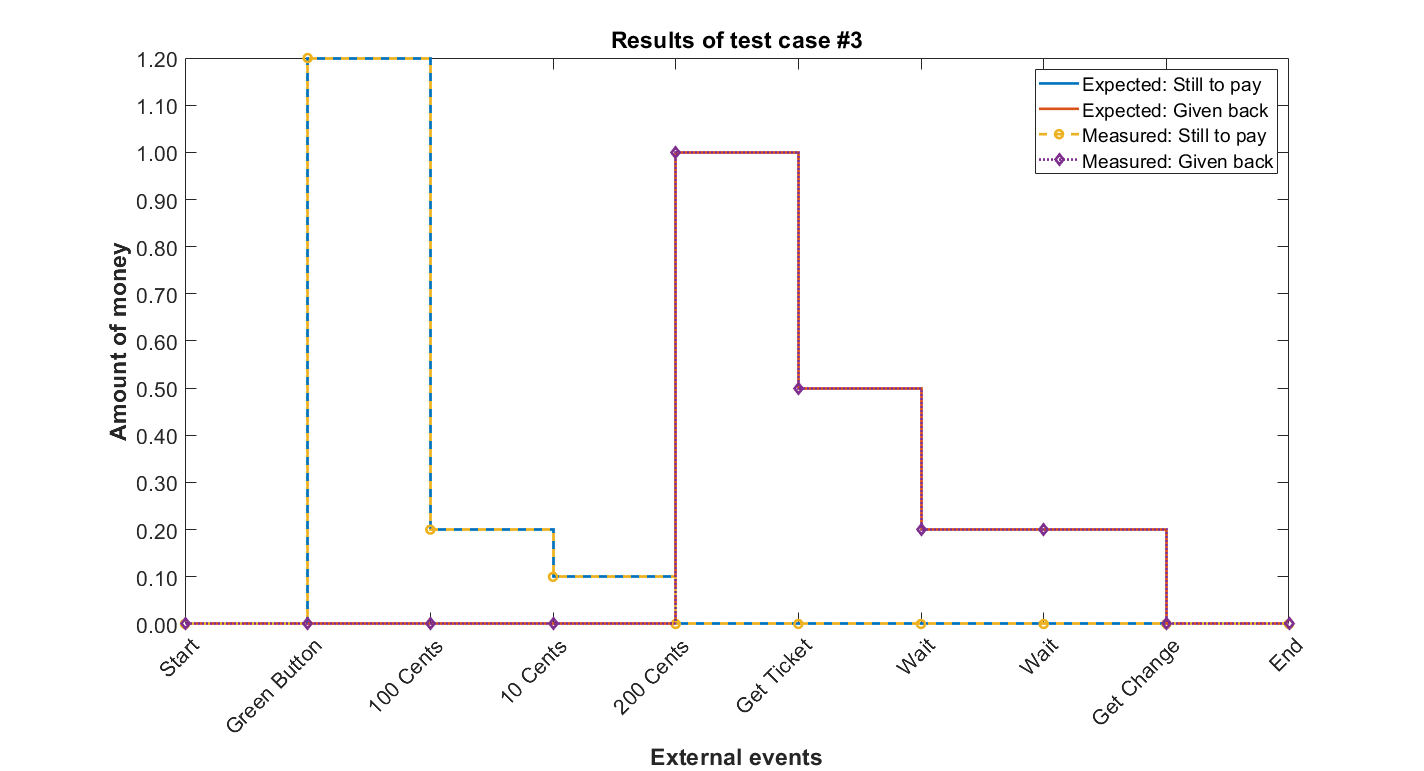


[Terse] Diagnostic logged (2021-02-17 10:56:01):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_f30163ac-2d80-488e-a9fb-54d45d9d78c3.fig
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_f30163ac-2d80-488e-a9fb-54d45d9d78c3.png
.

 Processing the test case #4...


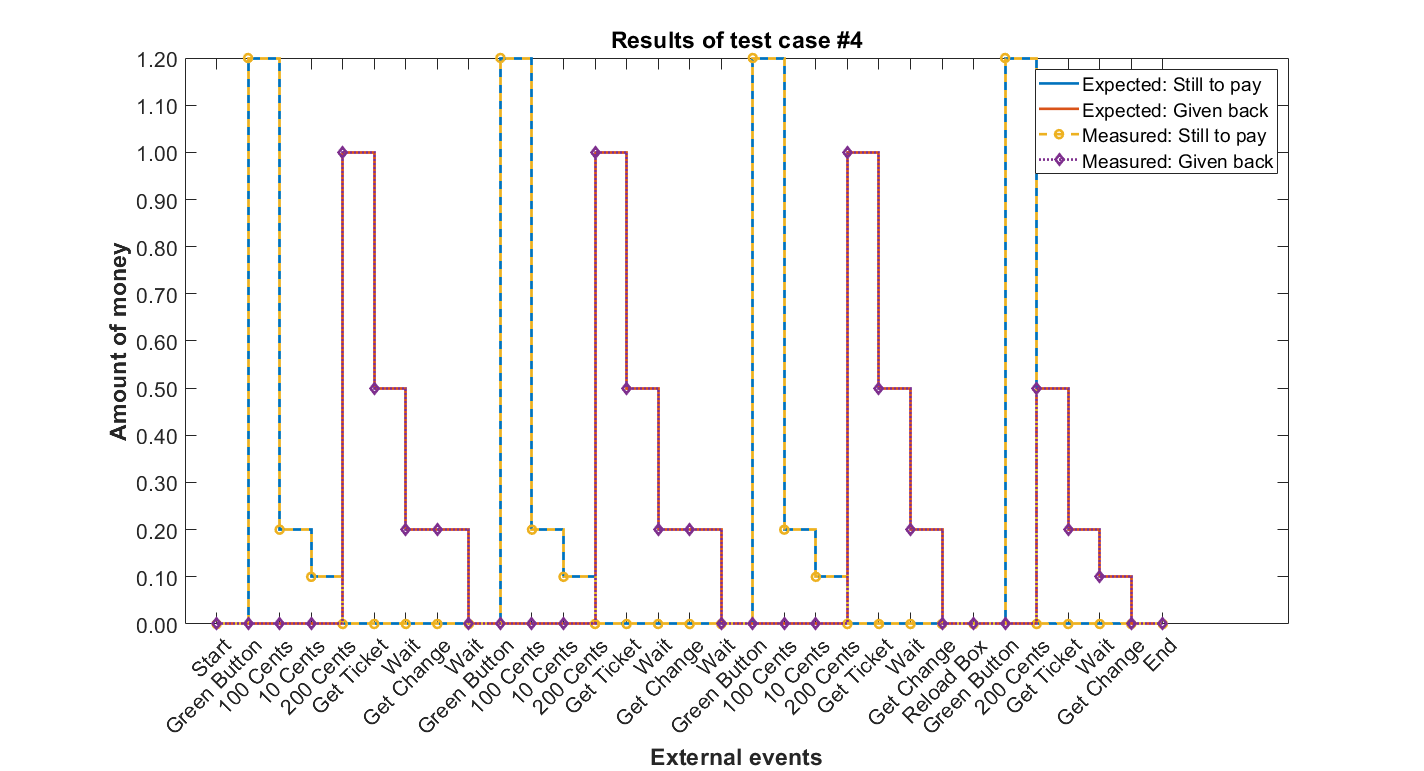


[Terse] Diagnostic logged (2021-02-17 10:57:33):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_54063ca0-dac7-4b4d-b1df-09cecedf6e8a.fig
--> C:\Users\sebas\AppData\Local\Temp\1d7ee206-d8af-4d14-b717-7f22c96501dd\Figure_54063ca0-dac7-4b4d-b1df-09cecedf6e8a.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.


    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tpe5771e38_bef9_4733_a6ee_6a7c0979779a\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false        27.704     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        24.443     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    true      false       false        31.474     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    true      false       false        92.096     {1×1 struct}

